**The Tabular value-fucntion methods on the cart and pole system**

Consider the cart-and-pole system here depicted:

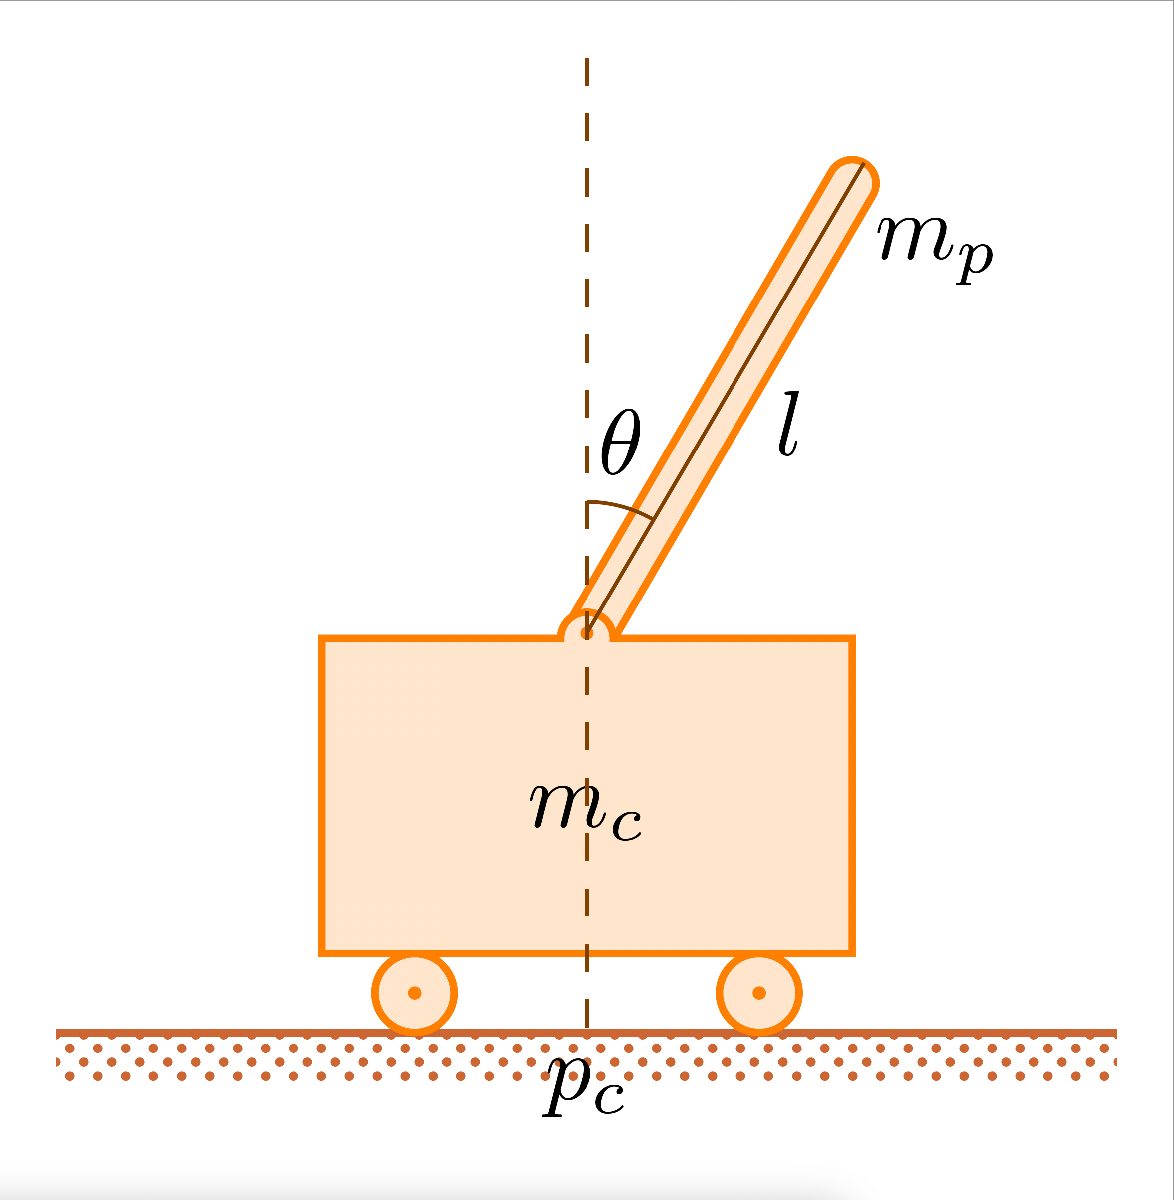

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient.

- Given the $$\mathcal{X}$$, $$\mathcal{U}$$ of the first hands-on define: the set of possible initial conditions of an episode; the terminal conditions of the episode

% Answer: (Arguing the answer)

The set of all possible initial condition is defined as follows:

The angle $x_1=\theta_i\in
[-\pi/2,\pi/2]
$ so the pole is free to rotate 180° totall

Supposing that the $x_2 \in  \mathbb{R}$ that's the angular velocity of the pole, is not exceeding $|x_2|<10 {rad\over s^2}$

$x3 \in  \mathbb{R}$, the cart is free to move along x axis parallel to the ground, 

$x4 \in  \mathbb{R}$, that is the velocity of the cart, that for example if a constant force is applied, it will move increasing his velocity


$$\$$


        2. Provide a proper discretization of the state space $$\mathcal{X}$$, and define the size of the action-value function $Q$

% Answer: (Arguing the answer)

clc;
clear all;
g=9.8 ;
mc=1;
mp=0.1;
l=0.5;
mu_p=0.000002;


intervalIndex=zeros(1,4); 
% Define your intervals
interval1 = [-inf,deg2rad(-12),-deg2rad(-4),deg2rad(4),deg2rad(12), +inf];%angolo
interval2= [-inf,-0.5,-0.2, 0.2,0.5, +inf];%velocita angolare
interval3=[-inf,-1,-0.5,0.5, 1,+inf];%posizione
interval4=[-inf,-0.5,-0.1, 0.1,0.5, +inf];%velocita carrello



 Q=zeros(size(interval1,2)-1,size(interval2,2)-1,size(interval3,2)-1,size(interval4,2)-1,2); 
 size(Q)

ans =      5     5     5     5     2


        3. Create a code able to select the discretized version of a measured state $x$

% Provide the code
test=[0,4,5,2];
discretization(test)%function at the end of the code

ans =      2     5     5     5


       4. Given the terminal conditions of the episode (selected in 1.) create a code able to perform a fixed number of episodes of a fixed number of steps, starting from random initial conditions and applying random inputs.

Look at part 6.

      5. Create a function able to perform $$\epsilon$$-greedy policy for a chosen $$\epsilon$$.

At the end of the script "epsilonGreedyPolicy"

      6. Create a code that applies Tabular Q-Learning algorithm.

% Provide the code
tic

% Q-learning parameters
alpha = 0.1;  % Learning rate
gamma = 0.95;  % Discount factor
%Tradeoff  between exploration and eploitation
tot_episode =6000; %total number of episode to perform
N=1000; %totale number of steps for each episode
U=0;%initializing the input 
timestep=0.02

timestep = 0.0200


reward_sum=0;% Initializing the total reward for each episode 
episodes_reward=zeros(tot_episode,1);%store reward sum for each episode
% Repeating for each episode 
last_episode=zeros(4,1);

for j=1:tot_episode
   
     x_initial=[rand(1,1)*0.01,0,rand(1,1)*0.01,0];%random initial condition


     reward_sum=0;%
   

        for i = 1:N

           if (x_initial(1)<=deg2rad(-12)) || (x_initial(1)>=deg2rad(12)) || ((x_initial(3)<=-1) || (x_initial(3)>=1 ))
           break;
           end
     

         
        u=epsilonGreedyPolicy(Q,x_initial,j);
        if j==tot_episode 

        last_episode=[last_episode,x_initial'];
        end
          stateNext=UpdateDynamics(x_initial,u)';

    
        stateNextDisc=discretization(stateNext);
        stateDisc=discretization(x_initial);

        reward = computeReward(stateNext,stateNextDisc);  %  reward function
   
        reward_sum=reward_sum+(gamma^(i-1))*reward;
        episodes_reward(j)=reward_sum;
    
        if u==-10 
            actionIndex=1;
        else
            actionIndex=2;
        end

   Q(stateDisc(1),stateDisc(2),stateDisc(3),stateDisc(4), actionIndex)=Q(stateDisc(1),stateDisc(2),stateDisc(3),stateDisc(4), actionIndex)+alpha*(reward+gamma*max(Q(stateNextDisc(1),stateNextDisc(2),stateNextDisc(3),stateNextDisc(4),:))- Q(stateDisc(1),stateDisc(2),stateDisc(3),stateDisc(4), actionIndex)); %compute the new Q(x^(k),u^(k))

    %evaluating if the states are out of bounds and then finish the episode in
       x_initial=stateNext;
       
        end
end
toc

Elapsed time is 694.635742 seconds.



%the row of Q corresponds to the discrete state considering the same row in combinazioni

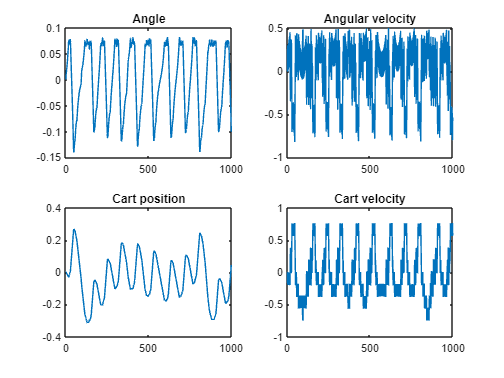




figure()
title("Q learnig")
subplot(2,2,1)
plot(1:size(last_episode,2),last_episode(1,:))

title('Angle');
subplot(2,2,2)
plot(1:size(last_episode,2),last_episode(2,:))

title('Angular velocity');
subplot(2,2,3)
plot(1:size(last_episode,2),last_episode(3,:))

title('Cart position');
subplot(2,2,4)

plot(1:size(last_episode,2),last_episode(4,:))
title('Cart velocity');

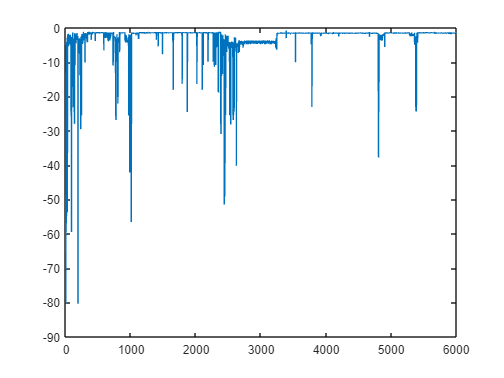

figure()
plot(episodes_reward)

      7. Copy and paste your Q-learning algorithm and apply the changes needed to convert it into a SARSA algorithm

% Provide the code
Q=zeros(size(interval1,2)-1,size(interval2,2)-1,size(interval3,2)-1,size(interval4,2)-1,2); 
 size(Q)

ans =      5     5     5     5     2



alpha = 0.1;  % Learning rate
gamma = 0.95;  % Discount factor
%Tradeoff  between exploration and eploitation
tot_episode =6000; %total number of episode to perform
N=1000; %totale number of steps for each episode
U=0;%initializing the input 

reward_sum=0;% Initializing the total reward for each episode 
episodes_reward1=zeros(tot_episode,1);%store reward sum for each episode
% Repeating for each episode 
last_episode1=zeros(4,1);





for j=1:tot_episode
   
     x_initial=[rand(1,1)*0.01,0,rand(1,1)*0.01,0];%random initial condition

     u=epsilonGreedyPolicy(Q,x_initial,j);%perform epsilon greedy policy

     reward_sum=0;%initializing total reward for each episode
   

  

        for i = 1:N

           if (x_initial(1)<=deg2rad(-12)) || (x_initial(1)>=deg2rad(12)) || ((x_initial(3)<=-1) || (x_initial(3)>=1 )) %terminal condition on angle and position
           break;
           end
     
        stateNext=UpdateDynamics(x_initial,u)'; %x(k+1)
        stateNextDisc=discretization(stateNext); %discretizing x(k+1)
        reward = computeReward(stateNext,stateNextDisc); %computing r(k+1)
      
        if u==-10 
            actionIndex=1;
        else
            actionIndex=2;
        end

        if j==tot_episode 
     
        last_episode1=[last_episode1,x_initial'];%saving last episode

        end

        u_next=epsilonGreedyPolicy(Q,stateNext,j); %u(k+1)

         if u_next==-10 
            actionIndex_next=1;
        else
            actionIndex_next=2;
        end

    
 
        stateDisc=discretization(x_initial);%discretizing x(k)

         %  reward function
   
        reward_sum=reward_sum+(gamma^(i))*reward;
        episodes_reward1(j)=reward_sum;

        Q(stateDisc(1),stateDisc(2),stateDisc(3),stateDisc(4), actionIndex)=Q(stateDisc(1),stateDisc(2),stateDisc(3),stateDisc(4), actionIndex)+...
        alpha*(reward+gamma*Q(stateNextDisc(1),stateNextDisc(2),stateNextDisc(3),stateNextDisc(4),actionIndex_next)- Q(stateDisc(1),stateDisc(2),stateDisc(3),stateDisc(4), actionIndex)); %compute the new Q(x^(k),u^(k))

    %evaluating if the states are out of bounds and then finish the episode in
    u=u_next;
       x_initial=stateNext;
       
        end
end
toc

Elapsed time is 5206.867785 seconds.


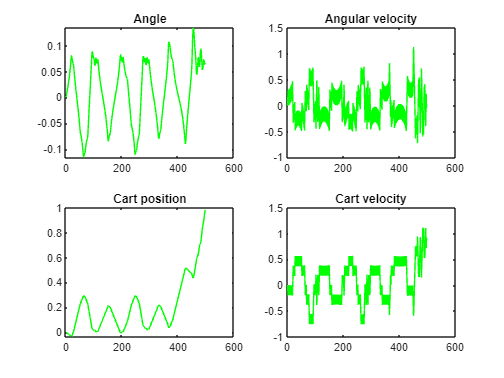



figure()
subplot(2,2,1)
plot(1:size(last_episode1,2),last_episode1(1,:),'g')

title('Angle');
subplot(2,2,2)
plot(1:size(last_episode1,2),last_episode1(2,:),'g')

title('Angular velocity');
subplot(2,2,3)
plot(1:size(last_episode1,2),last_episode1(3,:),'g')

title('Cart position');
subplot(2,2,4)

plot(1:size(last_episode1,2),last_episode1(4,:),'g')
title('Cart velocity');

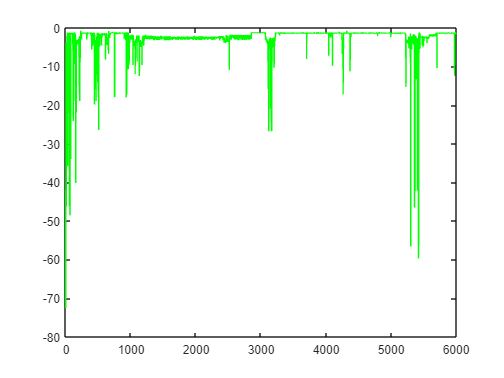






figure()
plot(episodes_reward1,'g')

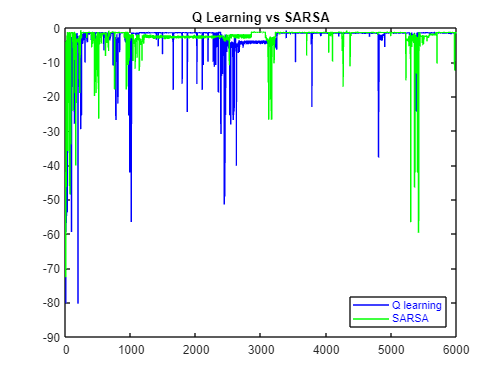


figure();

plot(episodes_reward,'b','DisplayName','Q learning');
hold on ;
plot (episodes_reward1,'g','DisplayName','SARSA');
title('Q Learning vs SARSA');
% Adding legend with specified colors
legend('Q learning', 'SARSA', 'TextColor', 'blue', 'Color', 'w', 'Location', 'southeast')

function reward=computeReward(state,intervalIndex)

     
     reward=-norm([state(1),state(3)]);

     if (state(1)<=deg2rad(-12)) || (state(1)>=deg2rad(12)) || ((state(3)<=-1) || (state(3)>=1))
        reward=reward-120;
    end


end

function index = findInterval(value, intervals)
    index = find(value <= intervals, 1, 'first') - 1;
end

function discreteState=discretization(state)
interval1 = [-inf,deg2rad(-12),-deg2rad(-4),deg2rad(4),deg2rad(12), +inf];%angolo
interval2= [-inf,-0.5,-0.2, 0.2,0.5, +inf];%velocita angolare
interval3=[-inf,-1,-0.5,0.5, 1,+inf];%posizione
interval4=[-inf,-0.5,-0.1, 0.1,0.5, +inf];%velocita carrello

intervalIndex(1,1) = findInterval(state(1,1), interval1);
intervalIndex(1,2) = findInterval(state(1,2), interval2);
intervalIndex(1,3) = findInterval(state(1,3), interval3);
intervalIndex(1,4) = findInterval(state(1,4), interval4);
discreteState=intervalIndex;
end







function u = epsilonGreedyPolicy(Q, state, j)
    epsilon = 1 / j;

    if rand() <= epsilon
        % Explore: Choose a random action
        selectedAction = randi(2);
        u = (selectedAction * 2 - 3) * 10; % Map index to action value
    else
        % Exploit: Choose the action with the highest estimated value
        discState = discretization(state);
        Q0 = Q(discState(1),discState(2), discState(3), discState(4), :);

        % Check if multiple actions have the same highest value
        if nnz(Q0 == max(Q0)) > 1
            selectedAction = randi(2); % Randomly choose between tied actions
        else
            [~, selectedAction] = max(Q0);
        end

        u = (selectedAction * 2 - 3) * 10; % Map index to action value
    end
end



function X_nl = UpdateDynamics(conds, u)
  % constants definition
g = 9.8; % gravitational acceleration
mc = 1;   % cart mass [kg]
l = 0.5; % half-pole length [m]
mp = 0.1; % pole mass [kg]
mup = 0.000002; % pole friction coefficient
t2=0;
X_nl = conds';
timestep = 0.02;
to_finish=0;
cont=true;
    t2=0;
    t1 = t2;
    t2 = t2+timestep;
    time = [t1, t2];
    [t,state] = ode45(@(t,x)solving1(t, x, g, u, mp, l, mc, mup), time, conds);
    tp = find(t == t2);
    conds = state(tp,:);
    X_nl = conds';
end



